clear
load data2.mat

Given from Data2Analysis

T=5; %[s]
fs=1/T; %[Hz]

Skraplacz=0.1*data.Skraplacz;
Kompresor1=data.Kompresor1;
Parownik1=0.1*data.Parownik1;
Wlot=0.1*data.Wlot;
TemperaturaOtoczenia=0.1*data.TemperaturaOtoczenia;
Rozmraanie=data.Rozmraanie;
WentylatorParownika=data.WentylatorParownika;
ZawrOdszraniania=data.ZawrOdszraniania;

X_all=[ZawrOdszraniania,Kompresor1,WentylatorParownika,Rozmraanie,...
    TemperaturaOtoczenia,Skraplacz,Wlot,Parownik1]';

[X,~]  = GetRidOfNans(X_all);
day=24*60*60*fs

day = 17280

t=T*(1:day);
X=X';
X=X(:,1:day);
size(X)

ans =            8       17280


n=length(t);
X_toFilter=X(5:8,:);
threshold=[0,5;0,5;-5,5;-5,5];
for i = 1:4
X_filtered(i,:) = InterpolateData(X_toFilter(i,:),threshold(i,:),t);
end

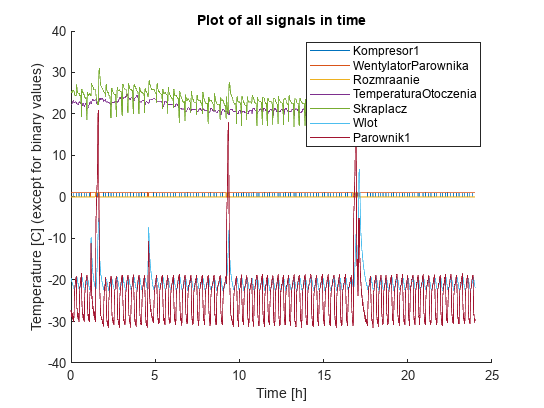

figure
hold on
for i = 2:4
    plot(t/(60*60),(X(i,:)))
end
for i = 1:4
    plot(t/(60*60),(X_filtered(i,:)))
end
xlabel('Time [h]')
ylabel('Temperature [C] (except for binary values)')
title('Plot of all signals in time')
legend('Kompresor1','WentylatorParownika','Rozmraanie',...
    'TemperaturaOtoczenia','Skraplacz','Wlot','Parownik1')
hold off

Example of using feature extraction algorythm using cycle detection:

[x,pks,locs]=featureWithPeakExtraction(X_filtered(3,:),0.01);

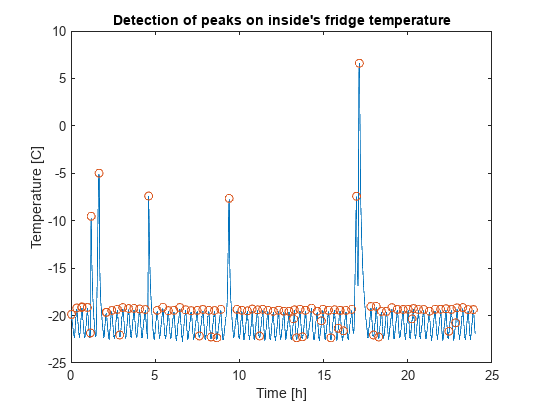

plot(t/(60*60),(X_filtered(3,:)));hold on
plot(t(locs(1:end))/(60*60),(pks),'o');hold off
title("Detection of peaks on inside's fridge temperature")
xlabel('Time [h]')
ylabel('Temperature [C]')

[x2,pks2,locs]=featureWithPeakExtraction(X_filtered(4,:),0.01);

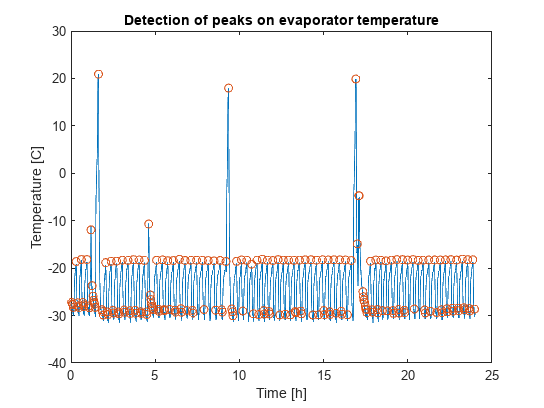

plot(t/(60*60),(X_filtered(4,:)));hold on
plot(t(locs(1:end))/(60*60),(pks2),'o');hold off
title('Detection of peaks on evaporator temperature')
xlabel('Time [h]')
ylabel('Temperature [C]')

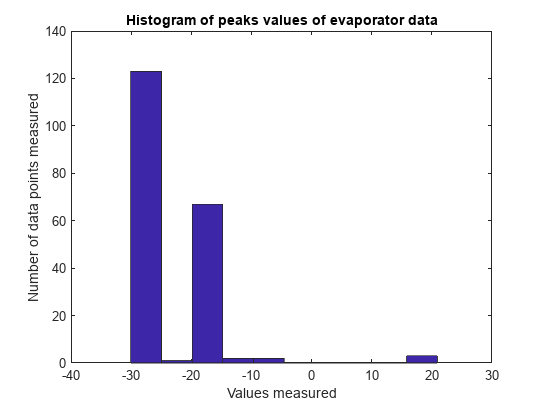

hist(pks2)
title("Histogram of peaks values of evaporator data")
xlabel('Values measured')
ylabel('Number of data points measured')

This example shows the unreliability of this method.

In conclusion, the filtering doesn't generalize the responce enough for local maxima detection to properly identify peaks. Looking at the histogram it would be easy to separate correct values by thresholding but this is not a general solution and has to be done manually by looking at data/historam and correctly selecting proper value range. Additionally this method doesn't actually properly identify cycles that occured during anolamy time (like fridge door opened for long time)

Using compressor state as cycle cryteria:

Let's assume the cycle starts when the compressor state goes from 0 to 1 (turns on).

previous_sample=0;
count=1;
clear locs
for i = 1:n
    current_sample=X(2,i);
    if previous_sample == 0 && current_sample ==1
    locs(count)=i;
    count=count+1;
    end
    previous_sample=current_sample;
end

% plot(t/(60*60),X(2,:),'-o',t(locs)/(60*60),ones(1,length(locs)),'o')

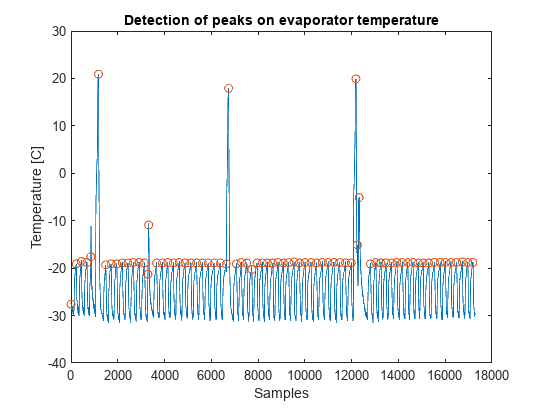

x = FeatureExtract(X_filtered(4,:),locs);
plot((X_filtered(4,:)));hold on
plot(locs,(X_filtered(4,locs)),'o');hold off
title('Detection of peaks on evaporator temperature')
xlabel('Samples')
ylabel('Temperature [C]')

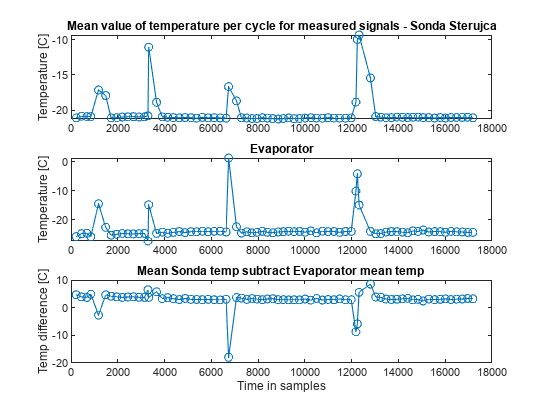

x_wlot = FeatureExtract(X_filtered(3,:),locs);
x_parownik = FeatureExtract(X_filtered(4,:),locs);
locs=locs(2:end);
figure

subplot(311)
plot(locs,x_wlot(3,:),'o-')
title('Mean value of temperature per cycle for measured signals - Sonda Sterujca')
ylabel('Temperature [C]')
% ylim([4,7])
subplot(312)
plot(locs,x_parownik(3,:),'o-')
title('Evaporator')
ylabel('Temperature [C]')
% ylim([4,7])
subplot(313)
plot(locs,x_wlot(3,:)-x_parownik(3,:),'o-')
title('Mean Sonda temp subtract Evaporator mean temp ')
xlabel('Time in samples')
ylabel('Temp difference [C]')

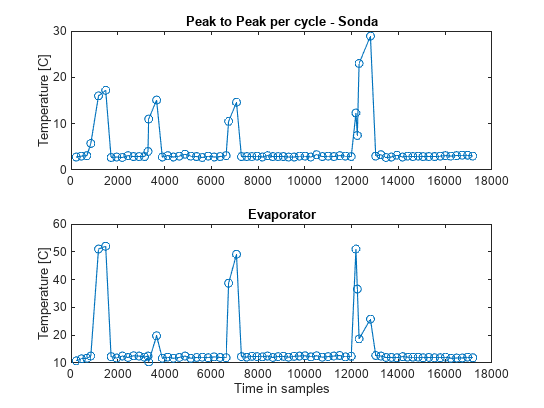

figure

subplot(211)
plot(locs,x_wlot(1,:)-x_wlot(2,:),'o-')
title('Peak to Peak per cycle - Sonda')
ylabel('Temperature [C]')
% ylim([4,7])
subplot(212)
plot(locs,x_parownik(1,:)-x_parownik(2,:),'o-')
title('Evaporator')
ylabel('Temperature [C]')
xlabel('Time in samples')

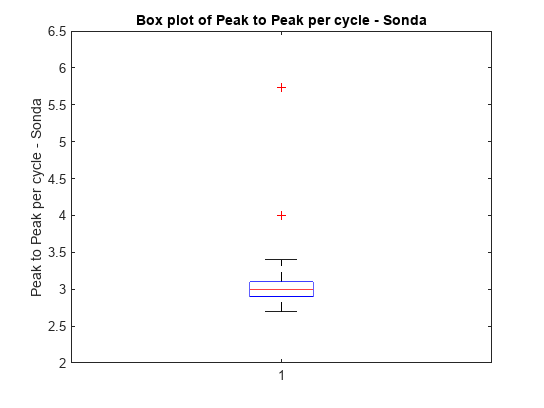

figure
fridge_air_temp_p2p=x_wlot(1,:)-x_wlot(2,:);
boxplot(fridge_air_temp_p2p)
ylabel('Peak to Peak per cycle - Sonda')
title("Box plot of Peak to Peak per cycle - Sonda")
ylim([2,6.5])

% ylim([4,7])
% subplot(313)
% plot(x_wlot(3,:)-x_parownik(3,:),'o-')
% title('Mean Sonda temp subtract Evaporator mean temp ')
% xlabel('Cycle')
% ylabel('Temp difference [C]')

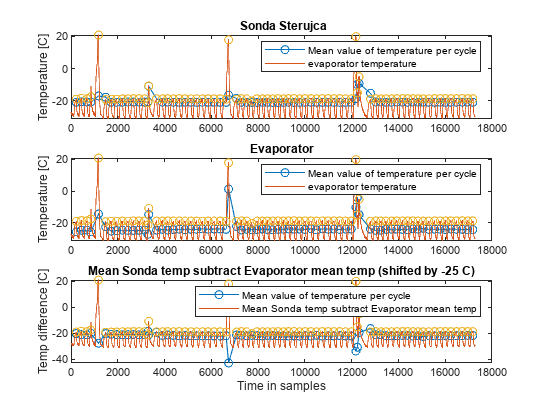

subplot(311)
plot(locs,x_wlot(3,:),'o-');hold on
plot((X_filtered(4,:)));
plot(locs,(X_filtered(4,locs)),'o');hold off
title(' Sonda Sterujca')
ylabel('Temperature [C]')
legend('Mean value of temperature per cycle','evaporator temperature')
% ylim([4,7])
subplot(312)
plot(locs,x_parownik(3,:),'o-');hold on
plot((X_filtered(4,:)));
plot(locs,(X_filtered(4,locs)),'o');hold off
title('Evaporator')
ylabel('Temperature [C]')
legend('Mean value of temperature per cycle','evaporator temperature')
% ylim([4,7])
subplot(313)
plot(locs,x_wlot(3,:)-x_parownik(3,:)-25,'o-');hold on
plot((X_filtered(4,:)));hold on
plot(locs,(X_filtered(4,locs)),'o');hold off
title('Mean Sonda temp subtract Evaporator mean temp (shifted by -25 C)')
xlabel('Time in samples')
ylabel('Temp difference [C]')
legend('Mean value of temperature per cycle','Mean Sonda temp subtract Evaporator mean temp')

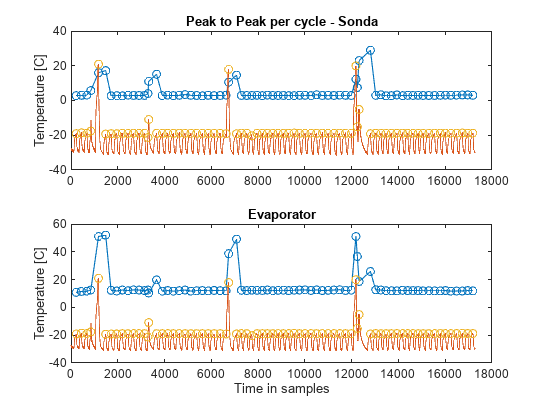

figure

subplot(211)
plot(locs,x_wlot(1,:)-x_wlot(2,:),'o-');hold on
plot((X_filtered(4,:)));
plot(locs,(X_filtered(4,locs)),'o');hold off
title('Peak to Peak per cycle - Sonda')
ylabel('Temperature [C]')
% ylim([4,7])
subplot(212)
plot(locs,x_parownik(1,:)-x_parownik(2,:),'o-');hold on
plot((X_filtered(4,:)));
plot(locs,(X_filtered(4,locs)),'o');hold off
title('Evaporator')
ylabel('Temperature [C]')
xlabel('Time in samples')

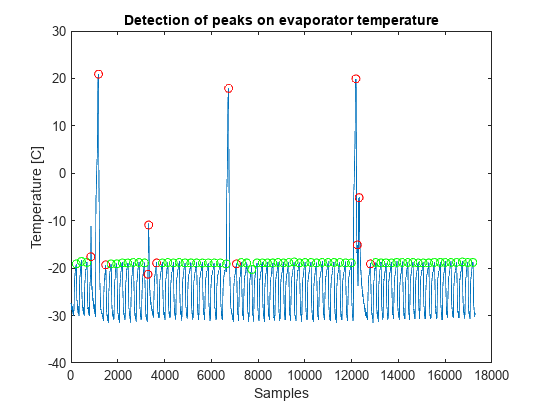

figure
TF = isoutlier(fridge_air_temp_p2p);
plot((X_filtered(4,:)));hold on
for i=1:length(x)
    if (TF(i)==1) 
        plot(locs(i),(X_filtered(4,locs(i))),'Marker','o',"Color",'red');
    elseif (TF(i)==0)
        plot(locs(i),(X_filtered(4,locs(i))),'Marker','o',"Color",'green');
    end
end
% plot(locs,(X_filtered(4,locs)),'Marker','o',"Color",'green');
hold off
title('Detection of peaks on evaporator temperature')
xlabel('Samples')
ylabel('Temperature [C]')

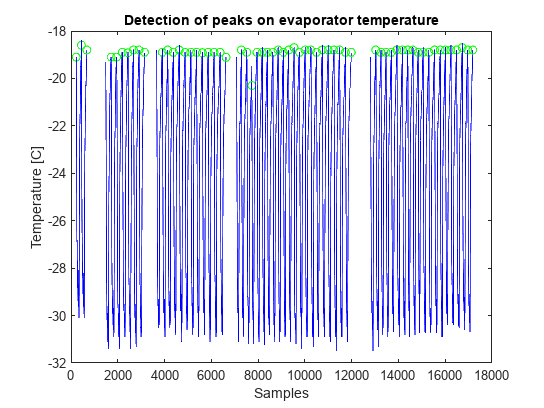

figure
TF = isoutlier(fridge_air_temp_p2p);
plot(locs(1),(X_filtered(4,locs(1))),'Marker','o',"Color",'green');hold on
for i=2:length(x)
    if (TF(i)==0)
        plot(locs(i-1):locs(i),(X_filtered(4,locs(i-1):locs(i))),"Color",'blue');
        plot(locs(i),(X_filtered(4,locs(i))),'Marker','o',"Color",'green');
    end
end
% plot(locs,(X_filtered(4,locs)),'Marker','o',"Color",'green');
hold off
title('Detection of peaks on evaporator temperature')
xlabel('Samples')
ylabel('Temperature [C]')

function [x,pks,locs]=featureWithPeakExtraction(data,wpass)
[x,d]=lowpass(data,wpass);
filter_order=length(d.Coefficients);

%Scaling the filtered signal 
group_delay = floor((length(filter_order) - 1)/2);
x = x(group_delay+1:end);

scale_factor = max(data) / max(x);
x = x * scale_factor;

[pks,locs] = findpeaks(x);

x = FeatureExtract(x,locs);
end